# DTMC SIS Model

## The Model

A **Discrete Time Markov Chain model** belongs to the class of stochastic models. However, its peculiarity consists in regarding the time as a discrete variable rather than a continuous one. Here, the attention is drawn on the probability distribution of the disease outbreak in the case of an SIS model.

The image below shows what the Markov chain for the SIS model looks like.

% imshow('SIS_Markov_chain.jpg')

## **The Simulation**

The **probability distribution** of infection depends on the time step and the number of infected. In other words, each combination of the values that these two variables can take on results in a probability value of infection. The **joint probability function** of the process is denoted as:


$$p_{(s,i)}(t) = Prob\{S(t) = s, I(t) = i\}$$


During each step, either an infection, a birth, a death or a recovery can occur. The transition probabilities can be expressed as:


$$p_{(s+k,i+j),(s,i)}(\Delta t) = Prob\{(\Delta S, \Delta I) = (k,j) | (S(t), I(t)) = (s,i)\}$$


Reset environment:

clear all

set(gca, 'FontSize', 18);
set(0, 'DefaultAxesFontSize', 18);

SImulation time:

time = 2000;

Time step:

dtt = 0.01;

Contact rate:

beta = 1 * dtt;

Birth rate:

b = 0.25 * dtt;

Recovery rate:

gamma = 0.25 * dtt;

Population size:

N = 100;

R_0 = beta / (gamma + b)

R_0 = 2

Jump between two time steps:

en = 50;

Preparation of arrays: **(what are v and p?)**

T = zeros(N + 1, N + 1);      % T is the transition matrix, defined below
v = linspace(0, N, N + 1);
p = zeros(time + 1, N + 1);
p(1,3) = 1;                   % Two individuals initially infected.

State vectors: **(what are bt and dt and why are they defined as such?)**

bt = beta * v .* (N - v) / N;
dt = (b + gamma) * v;

Transition matrix: **(why is the transition matrix built in this way?)**

for i = 2:N
    
    T(i,i) = 1 - bt(i) - dt(i);  % diagonal entries
    T(i, i + 1) = dt(i + 1);     % superdiagonal entries
    T(i + 1, i) = bt(i);         % subdiagonal entries
    
end

T(1,1) = 1;
T(1,2) = dt(2);
T(N + 1, N + 1) = 1 - dt(N + 1);

Probability matrix:

for t = 1:time
    
    y = T * p(t, :)';
    p(t + 1, :) = y';
    
end

pm(1, :) = p(1, :);

for t = 1:time / en

    pm(t + 1, :) = p(en * t, :);

end

Plot of the probability distribution:

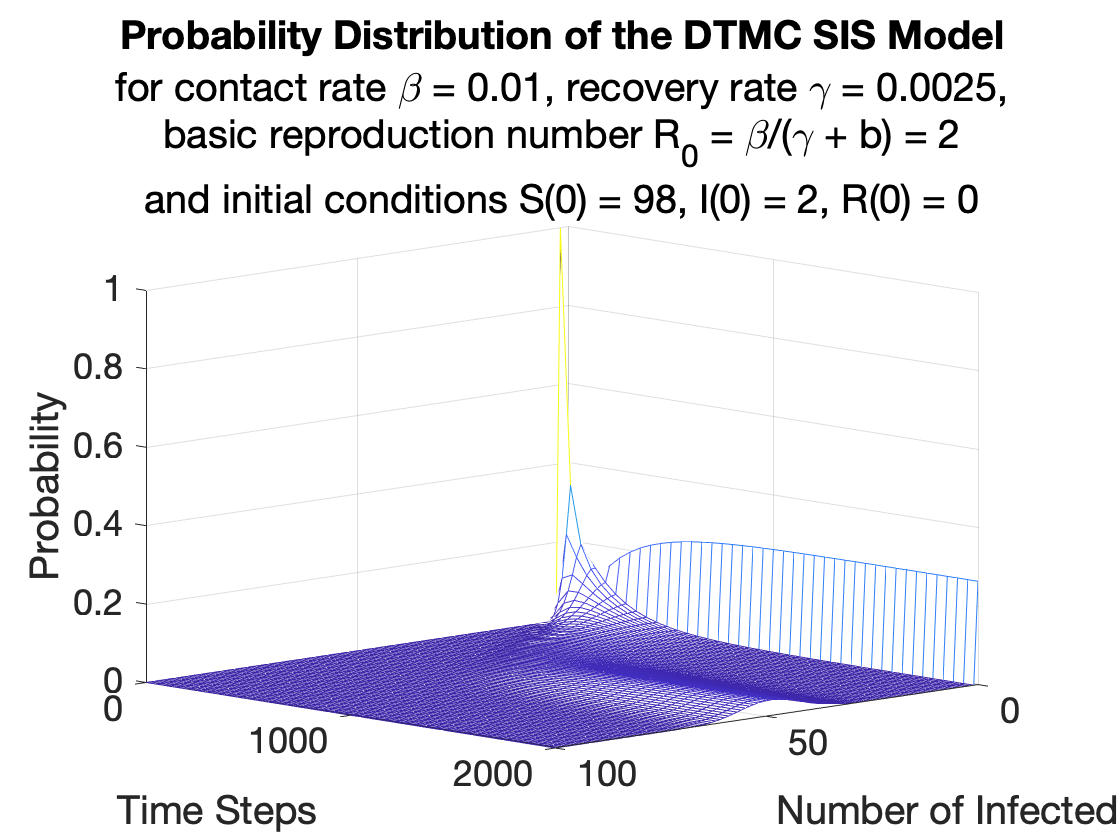

ti = linspace(0, time, time / en + 1);
st = linspace(0, N, N + 1);

mesh(st, ti, pm);
hold on

xlabel('Number of Infected');
ylabel('Time Steps');
zlabel('Probability');

title('Probability Distribution of the DTMC SIS Model')
subtitle({['for contact rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
['basic reproduction number R_0 = \beta/(\gamma + b) = ',num2str(R_0)], ['and initial conditions S(0) = ',num2str(N - 2),', I(0) = ',num2str(2),', R(0) = ',num2str(0)]})

view(140, 30);
axis([0, N, 0, time, 0, 1]);
hold off